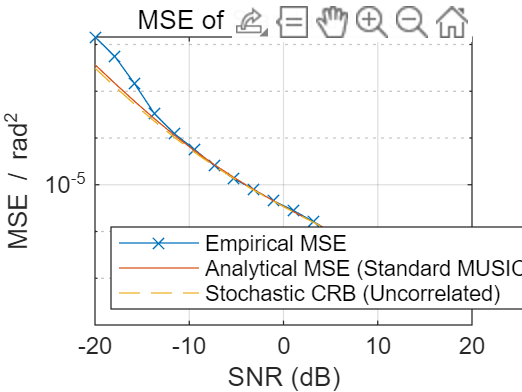

% Performance evaluation of ULA-based standard MUSIC
clear(); close all;

% Set up
wavelength = 1; % normalized
d = wavelength / 2;
n_elements = 10; % number of elements in ULA
design = design_array_1d('ula', n_elements, d);
doas = linspace(-pi/3, pi/3, 6); % 6 sources (corrected comment: previously said 2 sources)
power_source = 1;
snapshot_count = 500; % snapshots
source_count = length(doas);
grid_size = 2000; % spectrum resolution

% Vary SNR from -20 dB to 20 dB
n_param_power_noise = 20;
param_power_noise = 10.^(-linspace(-20, 20, n_param_power_noise)/10);
n_repeat = 200;
mse_em = zeros(n_param_power_noise, 1);
mse_an = zeros(n_param_power_noise, 1);
crb = zeros(n_param_power_noise, 1);
snr = zeros(n_param_power_noise, 1);

for ii = 1:n_param_power_noise
    power_noise = param_power_noise(ii);
    snr(ii) = 10*log10(power_source / power_noise);
    cur_se = 0;
    valid_count = 0;
    for rr = 1:n_repeat
        [~, R, ~] = snapshot_gen_sto(design, doas, wavelength, snapshot_count, power_noise, power_source);
        sp = music_1d(R, source_count, design, wavelength, grid_size, ...
            'Unit', 'radian', 'RefineEstimates', true); % Enable DOA refinement
        if sp.resolved && ~isempty(sp.x_est) && length(sp.x_est) == source_count
            % Ensure DOA estimates are sorted to match true DOAs
            [~, idx] = sort(sp.x_est);
            sorted_x_est = sp.x_est(idx);
            [~, idx_doas] = sort(doas);
            sorted_doas = doas(idx_doas);
            cur_se = cur_se + sum((sorted_x_est - sorted_doas).^2);
            valid_count = valid_count + 1;
        end
    end
    if valid_count > 0
        mse_em(ii) = cur_se / (source_count * valid_count);
    else
        mse_em(ii) = NaN; % mark invalid
    end
    % 使用标准MUSIC的ecov
    C = ecov_music_1d(design, wavelength, doas, power_source, power_noise, snapshot_count);
    mse_an(ii) = mean(diag(C));
    crb(ii) = mean(diag(crb_uc_sto_1d(design, wavelength, doas, power_source, power_noise, snapshot_count)));
end
fprintf('\n');

% --- Plot, remove NaNs ---
valid_idx = ~isnan(mse_em); % 找到有效的索引

figure;
semilogy(snr(valid_idx), mse_em(valid_idx), '-x', ...
         snr, mse_an, '-', ...
         snr, crb, '--');
xlabel('SNR (dB)');
ylabel('MSE / rad^2');
grid on;
legend('Empirical MSE', 'Analytical MSE (Standard MUSIC)', 'Stochastic CRB (Uncorrelated)', 'Location', 'southwest');
title('MSE of Standard MUSIC');